## Load data and nets

clear
currentFolder = fileparts(matlab.desktop.editor.getActiveFilename);
addpath(fullfile(currentFolder, '..', 'src'));
dataFolder = fullfile(currentFolder, '..', 'data');
modelBaseDir = fullfile(currentFolder, '..', 'models', 'LSTM');

zoneIds = [8, 9, 10, 11];
zoneNames = ["Anagnina", "Trieste", "Della Vittoria", "Tor di Quinto"];
windowSize = 48;
targetName = "AAC_energy";

numZones = numel(zoneIds);
zoneDataList = cell(numZones, 1);
zoneSplitList = cell(numZones, 1);
modelsList = cell(numZones, 1);

for i = 1:numZones
    zId = zoneIds(i);
    zoneData = loadZoneData(dataFolder, zId);

    hours = hour(zoneData.datetime) + minute(zoneData.datetime)/60;
    zoneData.cosHour = cos(2 * pi * hours / 24);
    zoneData.sinHour = sin(2 * pi * hours / 24);

    zoneDir = fullfile(modelBaseDir, sprintf("Zone%d", zId));
    matFiles = dir(fullfile(zoneDir, "LSTM_Zone*.mat"));
    if isempty(matFiles)
        error("Model file not found for Zone %d in directory %s", zId, zoneDir);
    end

    rmseValues = zeros(numel(matFiles), 1);
    for f = 1:numel(matFiles)
        tokens = regexp(matFiles(f).name, 'RMSE([\d.]+)', 'tokens', 'once');
        if ~isempty(tokens)
            rmseValues(f) = str2double(tokens{1});
        else
            rmseValues(f) = Inf;
        end
    end
    [~, bestIdx] = min(rmseValues);

    modelData = load(fullfile(zoneDir, matFiles(bestIdx).name));
    modelsList{i} = modelData;

    [~, ~, testData, ~] = splitZoneData(zoneData, windowSize, modelData.predictorNames, targetName);
    zoneDataList{i} = zoneData;
    zoneSplitList{i} = testData;
end

Data for zone "Zone_1016_Anagnina" loaded correctly (2784 rows x 17 columns).


Split completed: 1824 train, 384 val, 384 test samples.


Data for zone "Zone_214_Trieste" loaded correctly (2784 rows x 17 columns).


Split completed: 1824 train, 384 val, 384 test samples.


Data for zone "Zone_2004_Della Vittoria,Tomba di Nerone,Tor di Quinto2" loaded correctly (2784 rows x 17 columns).


Split completed: 1824 train, 384 val, 384 test samples.


Data for zone "Zone2002_Tor di Quinto6" loaded correctly (2784 rows x 17 columns).


Split completed: 1824 train, 384 val, 384 test samples.


## Cross-zone evaluation (Zero-shot vs Scale-adapted)

zeroShotRMSE = zeros(numZones, numZones);
scaleAdaptedRMSE = zeros(numZones, numZones);

for src = 1:numZones
    net = modelsList{src}.LSTMnet;
    srcNorm = modelsList{src}.normParams;

    for tgt = 1:numZones
        tgtTest = zoneSplitList{tgt};
        tgtMean = modelsList{tgt}.normParams.muTarget;
        tgtStd = modelsList{tgt}.normParams.sigmaTarget;

        tgtXRaw = cell(numel(tgtTest.X), 1);
        for k = 1:numel(tgtTest.X)
            tgtXRaw{k} = tgtTest.X{k} .* modelsList{tgt}.normParams.sigma + modelsList{tgt}.normParams.mu;
        end

        tgtX_srcNorm = cell(numel(tgtTest.X), 1);
        for k = 1:numel(tgtTest.X)
            tgtX_srcNorm{k} = (tgtXRaw{k} - srcNorm.mu) ./ srcNorm.sigma;
        end

        yNorm = minibatchpredict(net, tgtX_srcNorm, SequencePaddingDirection="left");

        tReal = tgtTest.T .* modelsList{tgt}.normParams.sigmaTarget + modelsList{tgt}.normParams.muTarget;

        yZeroShot = yNorm .* srcNorm.sigmaTarget + srcNorm.muTarget;
        zeroShotRMSE(src, tgt) = rmse(yZeroShot, tReal);

        yScaleAdapted = yNorm .* tgtStd + tgtMean;
        scaleAdaptedRMSE(src, tgt) = rmse(yScaleAdapted, tReal);
    end
end

## Heatmaps and ASHRAE benchmark matrix

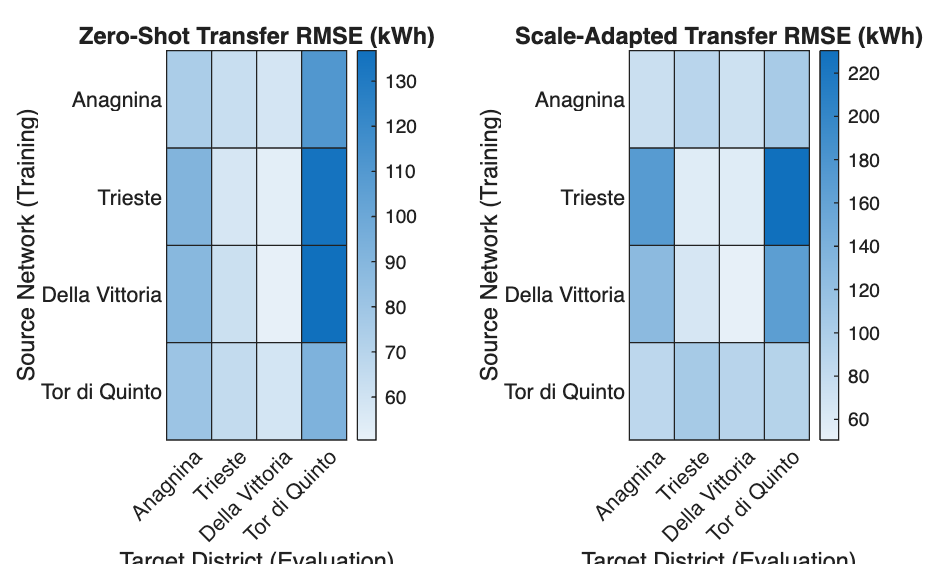

figure
tiledlayout(1, 2, Padding="compact", TileSpacing="compact")

nexttile
heatmap(zoneNames, zoneNames, zeroShotRMSE, CellLabelFormat="%.1f")
title("Zero-Shot Transfer RMSE (kWh)")
xlabel("Target District (Evaluation)")
ylabel("Source Network (Training)")

nexttile
heatmap(zoneNames, zoneNames, scaleAdaptedRMSE, CellLabelFormat="%.1f")
title("Scale-Adapted Transfer RMSE (kWh)")
xlabel("Target District (Evaluation)")
ylabel("Source Network (Training)")

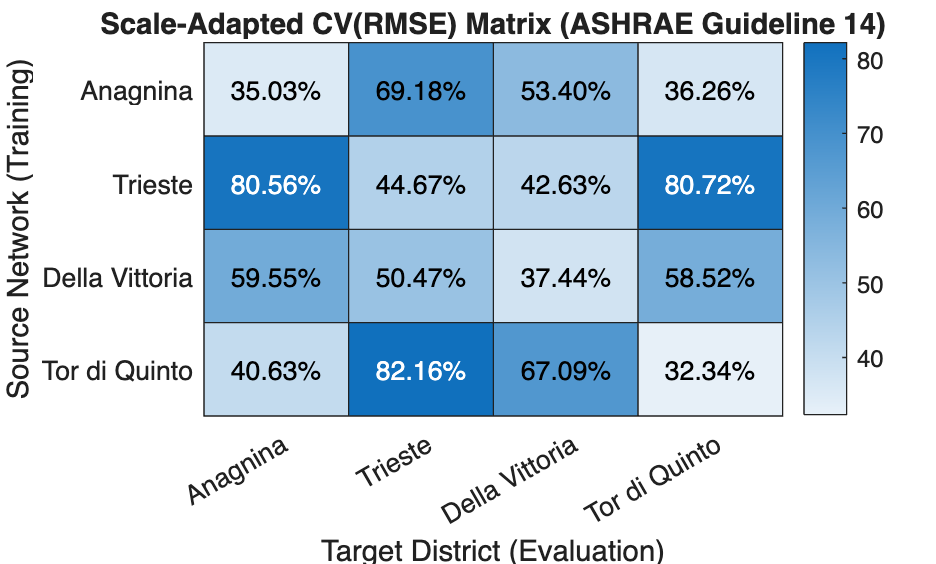

meanTargets = zeros(1, numZones);
for tgt = 1:numZones
    tReal = zoneSplitList{tgt}.T .* modelsList{tgt}.normParams.sigmaTarget + modelsList{tgt}.normParams.muTarget;
    meanTargets(tgt) = mean(tReal);
end

scaleAdaptedCV = (scaleAdaptedRMSE ./ meanTargets) * 100;

figure
heatmap(zoneNames, zoneNames, scaleAdaptedCV, CellLabelFormat="%.2f%%")
title("Scale-Adapted CV(RMSE) Matrix (ASHRAE Guideline 14)")
xlabel("Target District (Evaluation)")
ylabel("Source Network (Training)")

## Visual overlay (Measured vs Native vs Transferred)

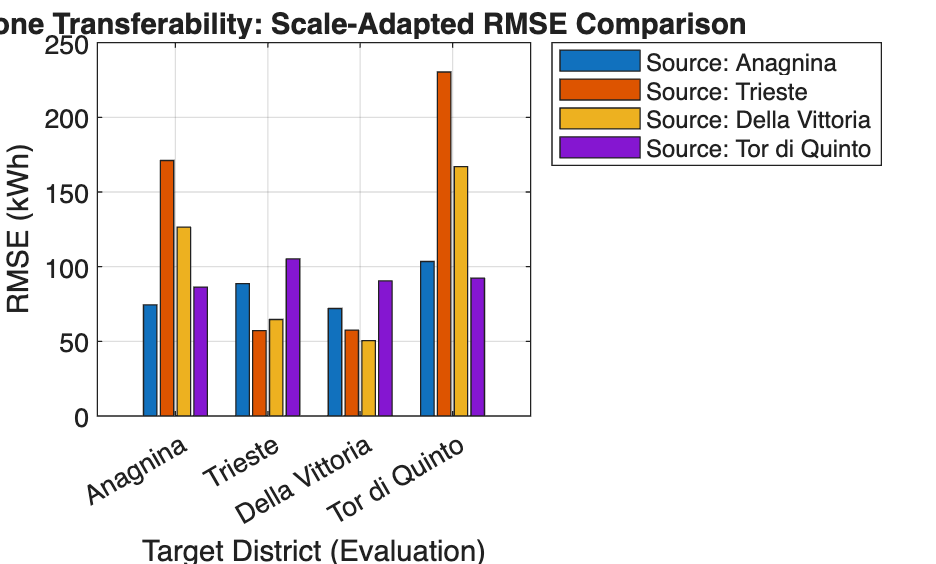

%% Section 4: Comprehensive Multi-Zone Visual Evaluation

% Grouped bar chart comparing native vs transferred performance across all 16 pairs
figure
bar(categorical(zoneNames, zoneNames), scaleAdaptedRMSE')
title("Cross-Zone Transferability: Scale-Adapted RMSE Comparison")
xlabel("Target District (Evaluation)")
ylabel("RMSE (kWh)")
legend(cellstr("Source: " + zoneNames), Location="northeastoutside")
grid on

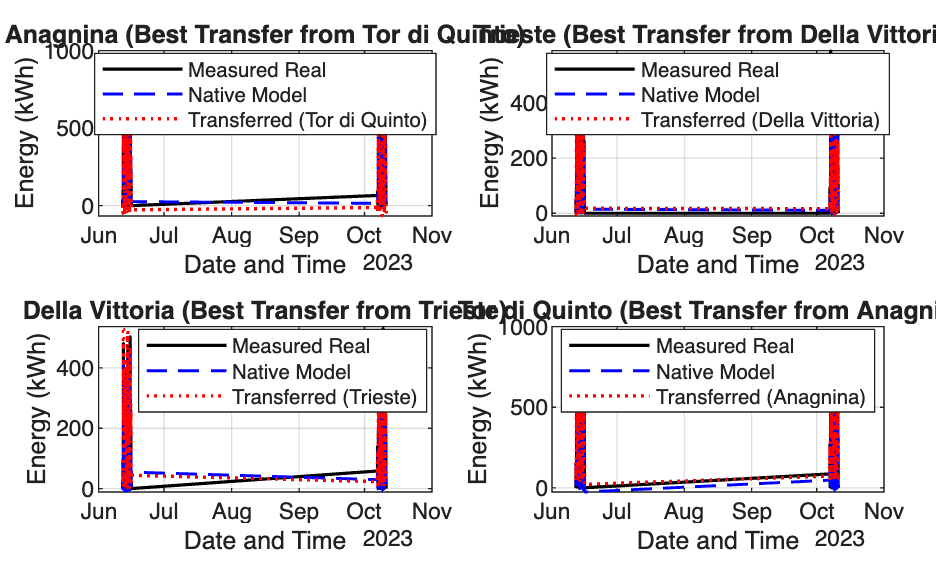


% Four-panel quadrant layout: One time series plot for each district
figure
tiledlayout(2, 2, Padding="compact", TileSpacing="compact")

for tgt = 1:numZones
    nexttile
    
    tgtTest = zoneSplitList{tgt};
    tReal = tgtTest.T .* modelsList{tgt}.normParams.sigmaTarget + modelsList{tgt}.normParams.muTarget;
    
    % Native model prediction
    nativeNet = modelsList{tgt}.LSTMnet;
    yNativeNorm = minibatchpredict(nativeNet, tgtTest.X, SequencePaddingDirection="left");
    yNative = yNativeNorm .* modelsList{tgt}.normParams.sigmaTarget + modelsList{tgt}.normParams.muTarget;
    
    % Find best transferred cross-zone model (excluding native)
    otherZones = setdiff(1:numZones, tgt);
    [~, bestOtherIdx] = min(scaleAdaptedRMSE(otherZones, tgt));
    bestSrc = otherZones(bestOtherIdx);
    
    srcNet = modelsList{bestSrc}.LSTMnet;
    srcNorm = modelsList{bestSrc}.normParams;
    
    tgtXRaw = cell(numel(tgtTest.X), 1);
    for k = 1:numel(tgtTest.X)
        tgtXRaw{k} = tgtTest.X{k} .* modelsList{tgt}.normParams.sigma + modelsList{tgt}.normParams.mu;
    end
    
    tgtX_srcNorm = cell(numel(tgtTest.X), 1);
    for k = 1:numel(tgtTest.X)
        tgtX_srcNorm{k} = (tgtXRaw{k} - srcNorm.mu) ./ srcNorm.sigma;
    end
    
    yTransNorm = minibatchpredict(srcNet, tgtX_srcNorm, SequencePaddingDirection="left");
    yTrans = yTransNorm .* modelsList{tgt}.normParams.sigmaTarget + modelsList{tgt}.normParams.muTarget;
    
    % Plot 4-day comparison
    plot(tgtTest.timestamps, tReal, "k-", LineWidth=1.2)
    hold on
    plot(tgtTest.timestamps, yNative, "b--", LineWidth=1.1)
    plot(tgtTest.timestamps, yTrans, "r:", LineWidth=1.3)
    hold off
    
    title(sprintf("%s (Best Transfer from %s)", zoneNames(tgt), zoneNames(bestSrc)))
    xlabel("Date and Time")
    ylabel("Energy (kWh)")
    legend(["Measured Real", "Native Model", sprintf("Transferred (%s)", zoneNames(bestSrc))], ...
        Location="best")
    grid on
end